# Evaluating gamma score for the epigenome-scale metabolic model

**Author:** Scott Campit

## Summary

This notebook performs several optimization and parameter tuning/search strategies for estimating histone acetylation and methylation.

**UPDATES**

*10/27/2020*

- First pass at evaluating the gamma score

- First pass at plotting different histone marker distributions

## 1. Load metabolic models

This code block loads specific versions of the eGEMM. There are currently two versions of the eGEMM:

- `07132020.mat:` contains all reactions from the metabolic model

- `09072020_write_only.mat`: contains only histone writer reactions

load ~/Data/Reconstructions/eGEM/07132020.mat; % Contains all reactions, including demethylation and deacetylation reactions

## 2. Evaluate gamma score

### Load data from the Cancer Cell Line Encyclopedia

This module uses RNASeq data from the CCLE and performs some basic preprocessing. The data was normalized to TPM. There are 864 cancer cell lines by 1020 metabolic genes that map onto RECON1 using Entrez identifiers.

load ~/Data/RNASeq/CCLE/CCLE_RNASeq.mat
load ~/Data/Proteomics/CCLE/CCLE_Proteomics.mat

### Get cell line intersections between the RNASeq dataset and the Global Chromatin Profiles

This is essential to ensure I'm making properr comparisons between datasets.

[~, ia, ib] = intersect(cell_lines, string(cell_names));
cell_lines = cell_lines(ia);
cell_names = cell_names(ib);

log2fc = log2fc(:, ia);
pvalue = pvalue(:, ia);

proteomics = proteomics(ib, :);
medium = medium(ib);
cultures = cultures(ib);
tissues = tissues(ib);

### Preprocess histone marker data

#### Ensure that histone readers and writers are being used in the metabolic model

First, let's get gene identifiers that are associated with histone writers and erasers.

% Load up curated histone reaction map
histoneReactionFile = '~/Data/Reconstructions/eGEM/Epigenome-Scale Metabolic Reconstruction Map.xlsx';
histoneReactionMap = readcell(histoneReactionFile, 'Sheet', 'Genes');
histoneReactionMap(ismissing(string(histoneReactionMap(:, 8))), :) = [];

% Edit Entrez 
histone_entrez = cell2mat(histoneReactionMap(2:end, 8));
histone_entrez = string(histone_entrez);

#### SANITY CHECK 1: Intersecting Entrez IDs between metabolic model and dataset

This code block just checks and sees if there are any intersecting genes with the metabolic model and the RNASeq data.

tmp1 = [];
tmp2 = [];
for j = 1:size(log2fc, 2)
        
    % Get differentially expressed genes for each cancer cell line.
    DE{j}.name    = cell_names(j);
    DE{j}.medium  = medium(j);
    DE{j}.culture = cultures(j);
    DE{j}.tissue  = tissues(j);
    DE{j}.upreg   = entrez_ids(log2fc(:, j) > 0 & pvalue(:, j) <= 0.05);
    DE{j}.downreg = entrez_ids(log2fc(:, j) < 0 & pvalue(:, j) <= 0.05);
    
    gene_list = [DE{j}.upreg; DE{j}.downreg];
    [~, ia, ib] = intersect(string(gene_list), string(histone_entrez));
    
    tmp1 = [tmp1; ia];
    tmp2 = [tmp2; ib];
    
end

Since tmp1 and tmp2 are not empty, we are getting some histone markers.

### Compute gamma matrix

This computes the gamma score for each demand reaction and for each cancer cell line.

% Get list of demand reactions from eGEMM
pos = [3773:3777, 3780:3799];
dm_reactions = string(eGEM.rxns(pos))';

% Get differentially expressed genes for each cancer cell line.
entrez_ids = string(entrez_ids);
eGEM.genes = eGEM.geneEntrezID;
gamma = zeros(length(dm_reactions), length(cell_lines));
for j = 1:length(dm_reactions)
    for k = 1:size(log2fc, 2)
        
        % Get differentially expressed genes
        DE{k}.upreg   = entrez_ids(log2fc(:, k) > 0 & pvalue(:, k) <= 0.05);
        DE{k}.downreg = entrez_ids(log2fc(:, k) < 0 & pvalue(:, k) <= 0.05);
        
        % Compute gamma score for each cell line
        gamma(j, k) = compute_gamma(eGEM, dm_reactions(j), histone_entrez, ...
                                    string(DE{k}.upreg), string(DE{k}.downreg));
    end
end

### Compute correlation between gamma matrix and histone PTMs

The idea behind this analysis is to see if we get a correlation between overall transcriptional activity and the histoone proteomics.

#### Bulk acetylation and acetylation markers

Extract the bulk acetylation proteomics and gamma score. From this analysis, and using $\alpha =0\ldotp 01$, we get H3K9ac, H3K14ac, and H3K23ac correct (and significant). There are no wrong predictions that are significant.

ac_gamma = gamma(1, :);

% CCLE
marks = regexprep(marks, 'K[0-9]*ac0', '');
marks = regexprep(marks, 'K[0-9]*me0', '');

acetylation_idx   = [4, ...  H3K4
                     9, ...  H3K9
                     10, ... H3K14
                     16, ... H3K18
                     17, ... H3K23
                     33];  % H3k27
acetylation_marks = marks(acetylation_idx)

acetylation_marks = 1×6 cell array
    {'H3K4ac1'}    {'H3K9ac1'}    {'H3K14ac1'}    {'H3K18ac1'}    {'H3K23ac1'}    {'H3K27ac1'}


acetylation_data = proteomics(:, acetylation_idx);

[ac_r, ac_p] = corr(ac_gamma', acetylation_data)

ac_r =     0.0344    0.1105    0.0999   -0.0795    0.0968   -0.0840


ac_p =     0.3255    0.0016    0.0043    0.0231    0.0056    0.0164


**Plot correlation between bulk acetylation gamma score and histone acetylation**

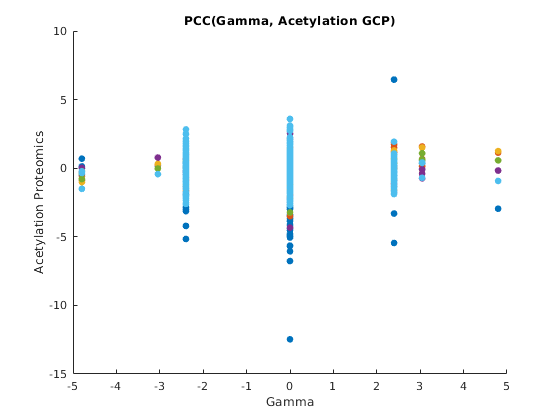

figure;
for i = 1:size(acetylation_data, 2)
    hold on;
    scatter(ac_gamma', acetylation_data(:, i), 'filled')
    hold off;
end
xlabel('Gamma'); ylabel('Acetylation Proteomics');
title('PCC(Gamma, Acetylation GCP)');

**Visualize gamma score distribution for bulk acetylation**

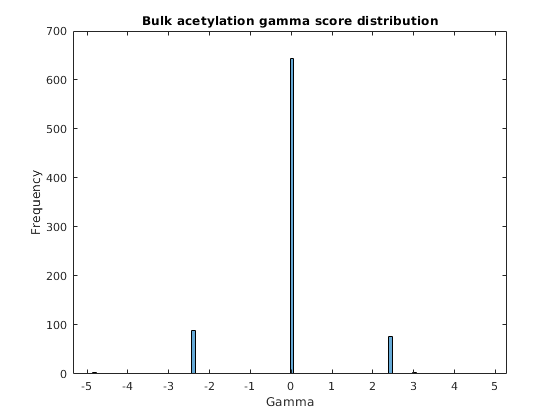

figure;
histogram(ac_gamma, 100);
xlabel('Gamma'); ylabel('Frequency');
title('Bulk acetylation gamma score distribution');

**Visualize acetylation Z-score distribution**

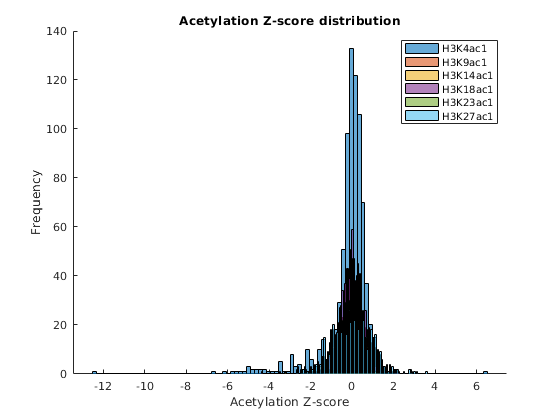

figure;
for i = 1:size(acetylation_data, 2)
    hold on; 
    histogram(acetylation_data(:, i), 100, ...
              'DisplayName', char(acetylation_marks(i)));
    hold off;
end
xlabel('Acetylation Z-score'); ylabel('Frequency');
title('Acetylation Z-score distribution');
legend;

#### Bulk monomethylation and monomethylation markers

Extract the bulk KMe1 proteomics and gamma score. From this analysis, and using $\alpha =0\ldotp 01$, we get H3K4me incorrect (and significant). There are no correct predictions that are significant.

me1_gamma = gamma(3, :);

me1_idx   = [2, 6, 21, 24, 39, 41];
me1_marks = marks(me1_idx)

me1_marks = 1×6 cell array
    {'H3K4me1'}    {'H3K9me1'}    {'H3K36me1'}    {'H3K27me1'}    {'H3K56me1'}    {'H3K79me1'}


me1_data  = proteomics(:, me1_idx);

[me1_r, me1_p] = corr(me1_gamma', me1_data)

me1_r =    -0.1833   -0.0884   -0.0151    0.0808    0.0511   -0.0451


me1_p =     0.0000    0.0115    0.6675    0.0209    0.1442    0.1975


**Plot correlation between bulk acetylation gamma score and Me1**

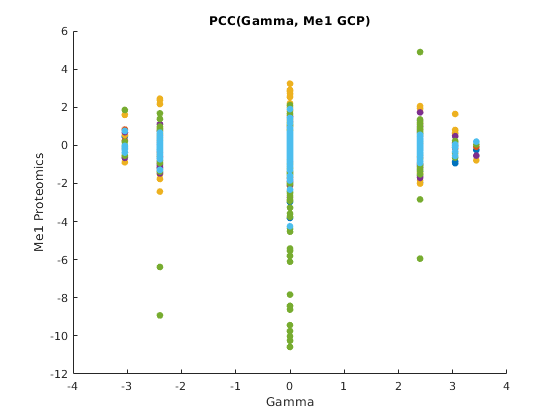

figure;
for i = 1:size(me1_data, 2)
    hold on;
    scatter(me1_gamma', me1_data(:, i), 'filled')
    hold off;
end
xlabel('Gamma'); ylabel('Me1 Proteomics');
title('PCC(Gamma, Me1 GCP)');

**Visualize gamma score distribution for bulk Me1**

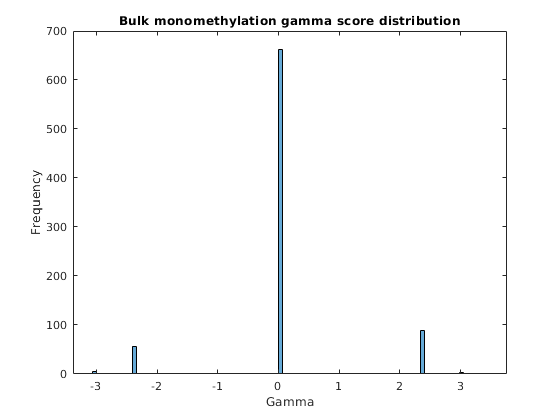

figure;
histogram(me1_gamma, 100);
xlabel('Gamma'); ylabel('Frequency');
title('Bulk monomethylation gamma score distribution');

**Visualize Me1 Z-score distribution**

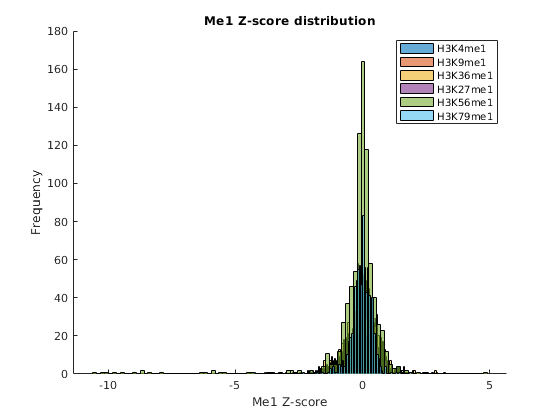

figure;
for i = 1:size(me1_data, 2)
    hold on; 
    histogram(me1_data(:, i), 100, ...
              'DisplayName', char(me1_marks(i)));
    hold off;
end
xlabel('Me1 Z-score'); ylabel('Frequency');
title('Me1 Z-score distribution');
legend;

#### Bulk dimethylation and dimethylation markers

Extract the bulk KMe2 proteomics and gamma score. From this analysis, and using $\alpha =0\ldotp 01$, there are no correct predictions.

me2_gamma = gamma(4, :);

me2_idx   = [3, 7, 22, 28, 42];
me2_marks = marks(me2_idx)

me2_marks = 1×5 cell array
    {'H3K4me2'}    {'H3K9me2'}    {'H3K36me2'}    {'H3K27me2'}    {'H3K79me2'}


me2_data  = proteomics(:, me2_idx);

[me2_r, me2_p] = corr(me2_gamma', me2_data)

me2_r =    -0.0835   -0.0421    0.0082    0.0357    0.0182


me2_p =     0.0170    0.2293    0.8146    0.3083    0.6039


**Plot correlation between bulk acetylation gamma score and Me2**

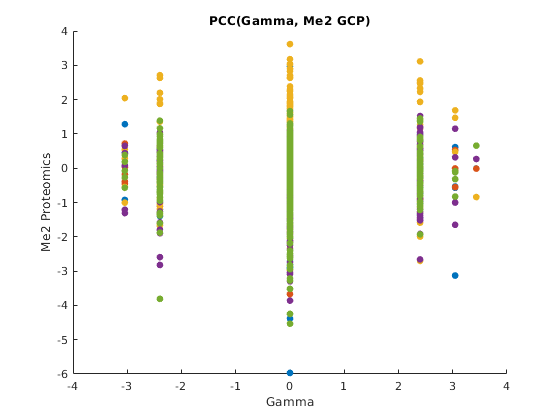

figure;
for i = 1:size(me2_data, 2)
    hold on;
    scatter(me2_gamma', me2_data(:, i), 'filled')
    hold off;
end
xlabel('Gamma'); ylabel('Me2 Proteomics');
title('PCC(Gamma, Me2 GCP)');

**Visualize gamma score distribution for bulk Me2**

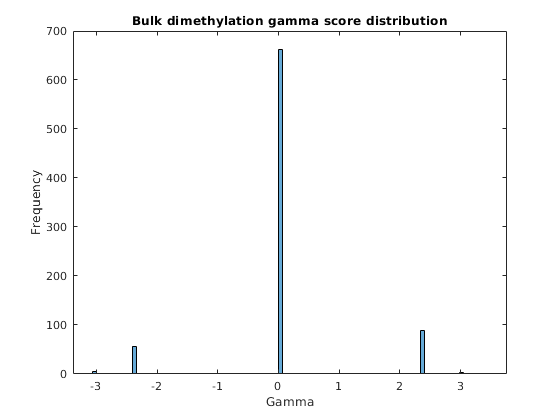

figure;
histogram(me2_gamma, 100);
xlabel('Gamma'); ylabel('Frequency');
title('Bulk dimethylation gamma score distribution');

**Visualize Me2 Z-score distribution**

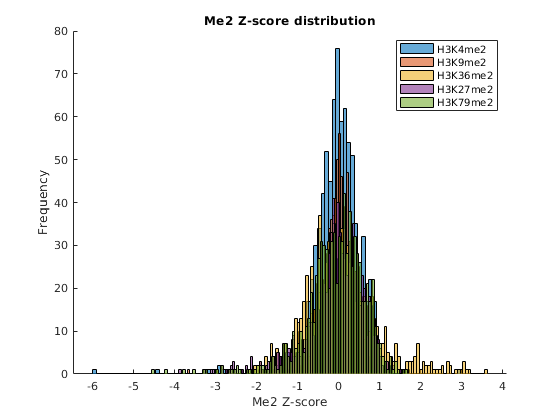

figure;
for i = 1:size(me2_data, 2)
    hold on; 
    histogram(me2_data(:, i), 100, ...
              'DisplayName', char(me2_marks(i)));
    hold off;
end
xlabel('Me2 Z-score'); ylabel('Frequency');
title('Me2 Z-score distribution');
legend;

#### Bulk trimethylation and trimethylation markers

Extract the bulk KMe2 proteomics and gamma score. From this analysis, and using $\alpha =0\ldotp 01$, there H3K27me3 is correct and H3K9me3 is incorrect.

me3_gamma = gamma(5, :);

me3_idx   = [8, 23, 31];
me3_marks = marks(me3_idx)

me3_marks = 1×3 cell array
    {'H3K9me3'}    {'H3K36me3'}    {'H3K27me3'}


me3_data  = proteomics(:, me3_idx);

[me3_r, me3_p] = corr(me3_gamma', me3_data)

me3_r =    -0.1139   -0.0004    0.1040


me3_p =     0.0011    0.9898    0.0029


**Plot correlation between bulk acetylation gamma score and Me3**

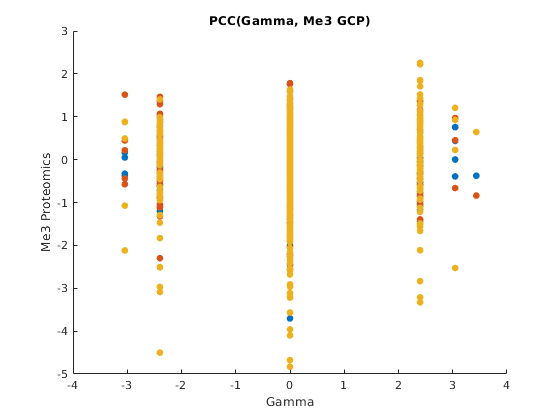

figure;
for i = 1:size(me3_data, 2)
    hold on;
    scatter(me3_gamma', me3_data(:, i), 'filled')
    hold off;
end
xlabel('Gamma'); ylabel('Me3 Proteomics');
title('PCC(Gamma, Me3 GCP)');

**Visualize gamma score distribution for bulk Me3**

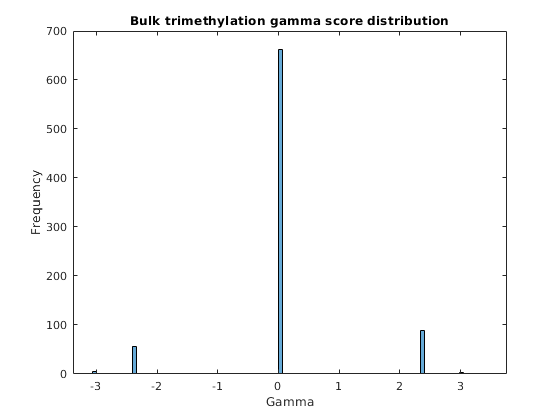

figure;
histogram(me3_gamma, 100);
xlabel('Gamma'); ylabel('Frequency');
title('Bulk trimethylation gamma score distribution');

**Visualize Me3 Z-score distribution**

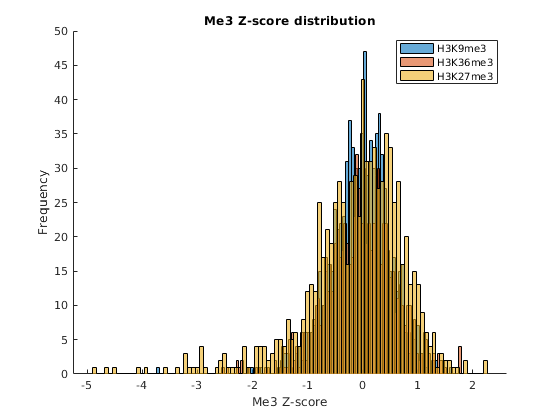

figure;
for i = 1:size(me3_data, 2)
    hold on; 
    histogram(me3_data(:, i), 100, ...
              'DisplayName', char(me3_marks(i)));
    hold off;
end
xlabel('Me3 Z-score'); ylabel('Frequency');
title('Me3 Z-score distribution');
legend;

#### Individual histone modifications 

Extract the bulk KMe2 proteomics and gamma score. From this analysis, and using $\alpha =0\ldotp 01$, correct prediction include H3K9ac. No other histone marker is statistically significant.

indv_gamma = gamma([6, 7, 9, ...        % H3K4  me1, me2, ac
                   10, 11, 12, 13, ...  % H3K9  me1, me2, me3, ac
                   14, 15, 16, 17, ...  % H3K27 me1, me2, me3, ac
                   18, 19, 20,     ...  % H3K36 me1, me2, me2
                   22, 23], :); % H3K79 me1, me2

indv_idx   = [2, 3, 4, ...        % H3K4 me1, me2, ac
              6, 7, 8, 9, ...     % H3K9 me1, me2, me3, ac
              24, 28, 31, 33, ... % H3K27 me1, me2, me3, ac
              21, 22, 23, ...     % H3K36 me1, me2, me2
              41, 42];            % H3K79 me1, me2
indv_marks = marks(indv_idx);
indv_prot  = proteomics(:, indv_idx);

[indv_r, indv_p] = corr(indv_gamma', indv_prot);
indv_r = diag(indv_r); indv_r = indv_r';
indv_p = diag(indv_p); indv_p = indv_p';
indv_data = [string(indv_marks); indv_r; indv_p]

indv_data = 3×16 string array
    "H3K4me1"     "H3K4me2"        "H3K4ac1"     "H3K9me1"       "H3K9me2"      "H3K9me3"      "H3K9ac1"     "H3K27me1"     "H3K27me2"      "H3K27me3"    "H3K27ac1"    "H3K36me1"     "H3K36me2"     "H3K36me3"    "H3K79me1"    "H3K79me2"
    "0.062844"    "-0.00060551"    "0.043527"    "-0.0055397"    "-0.018502"    "-0.022414"    "0.11333"     "-0.068605"    "-0.0068834"    "0.021218"    "-0.08998"    "-0.071867"    "-0.077629"    "0.033534"    <missing>     <missing> 
    "0.072604"    "0.98621"        "0.21393"     "0.87438"       "0.59745"      "0.52233"      "0.001175"    "0.049967"     "0.84426"       "0.54477"     "0.010076"    "0.040006"     "0.026499"     "0.33841"     <missing>     <missing> 


**Plot correlation for individual histone markers**

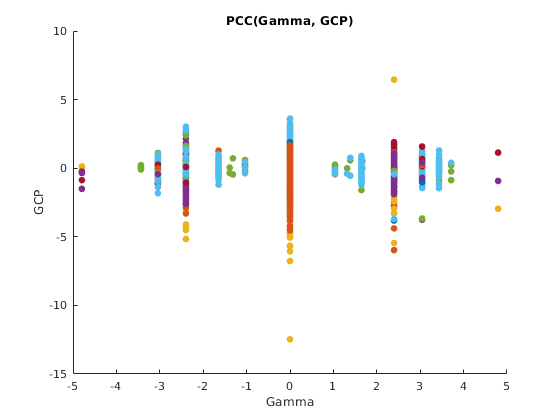

indv_gamma = indv_gamma';
figure;
for i = 1:size(indv_data, 2)
    hold on;
    scatter(indv_gamma(:, i), indv_prot(:, i), 'filled')
    hold off;
end
xlabel('Gamma'); ylabel('GCP');
title('PCC(Gamma, GCP)');

### Compute the gamma score accuracy

#### All correlation modifications

We will define a correct prediction as one that has a positive correlation.

all_pcc = [ac_r, me1_r, me2_r, me3_r, indv_r];
correct_corr = (sum(all_pcc > 0) / length(all_pcc))*100

correct_corr = 41.6667

incorrect_corr = 100 - correct_corr

incorrect_corr = 58.3333

#### Evaluating significant correlation modifications

all_marks = string([acetylation_marks, me1_marks, me2_marks, me3_marks, indv_marks]);


$$\alpha <0\ldotp 001$$


alpha = 0.001;
all_pval = [ac_p, me1_p, me2_p, me3_p, indv_p];
correct_corr = (sum(all_pcc > 0 & all_pval < alpha) / sum(all_pval < alpha))*100

correct_corr = 0

incorrect_corr = 100 - correct_corr

incorrect_corr = 100

num_of_good_sig_hits = sum(all_pcc > 0 & all_pval < alpha, 'all')

num_of_good_sig_hits = 0

num_of_all_sig_hits = sum(all_pval < alpha, 'all')

num_of_all_sig_hits = 1

all_marks(:, all_pcc > 0 & all_pval < alpha)


ans = 

  1×0 empty string array



all_pcc(all_pcc > 0 & all_pval < alpha)


ans =

  1×0 empty double row vector




$$\alpha <0\ldotp 01$$


alpha = 0.01;
all_pval = [ac_p, me1_p, me2_p, me3_p, indv_p];
correct_corr = (sum(all_pcc > 0 & all_pval < alpha) / sum(all_pval < alpha))*100

correct_corr = 71.4286

incorrect_corr = 100 - correct_corr

incorrect_corr = 28.5714

num_of_good_sig_hits = sum(all_pcc > 0 & all_pval < alpha, 'all')

num_of_good_sig_hits = 5

num_of_all_sig_hits = sum(all_pval < alpha, 'all')

num_of_all_sig_hits = 7

all_marks(:, all_pcc > 0 & all_pval < alpha)

ans = 1×5 string array
    "H3K9ac1"    "H3K14ac1"    "H3K23ac1"    "H3K27me3"    "H3K9ac1"


all_pcc(all_pcc > 0 & all_pval < alpha)

ans =     0.1105    0.0999    0.0968    0.1040    0.1133



$$\alpha <0\ldotp 05$$


alpha = 0.05;
all_pval = [ac_p, me1_p, me2_p, me3_p, indv_p];
correct_corr = (sum(all_pcc > 0 & all_pval < alpha) / sum(all_pval < alpha))*100

correct_corr = 37.5000

incorrect_corr = 100 - correct_corr

incorrect_corr = 62.5000

num_of_good_sig_hits = sum(all_pcc > 0 & all_pval < alpha, 'all')

num_of_good_sig_hits = 6

num_of_all_sig_hits = sum(all_pval < alpha, 'all')

num_of_all_sig_hits = 16

all_marks(:, all_pcc > 0 & all_pval < alpha)

ans = 1×6 string array
    "H3K9ac1"    "H3K14ac1"    "H3K23ac1"    "H3K27me1"    "H3K27me3"    "H3K9ac1"


all_pcc(all_pcc > 0 & all_pval < alpha)

ans =     0.1105    0.0999    0.0968    0.0808    0.1040    0.1133


## Conclusions

### Gamma score is well correlated for histone acetylation levels

The gamma score is correlated really well with several histone acetylation marker levels if we're considering a significance level of $\alpha <0\ldotp 01$. Additionally, for some reason, histone methylation levels are not really well correlated. 

### Follow up analyses

This leads me to suspect that I need to re-check several things:

- What is the structure of the expression dataset?

- Am I performing an adequate analysis of the expression dataset?

- What are some areas where my reconstruction can be going wrong in terms of gene-protein-reaction annotations?